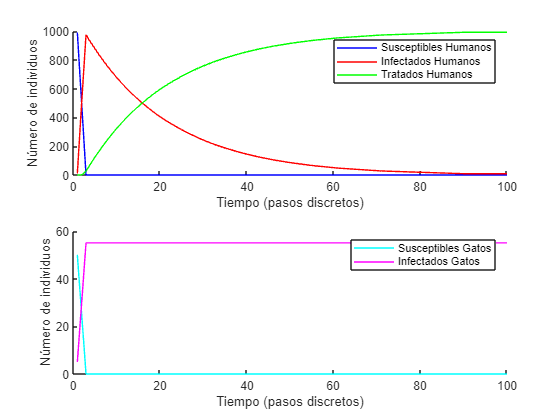

%%%Coded by Santiago Caballero Rosas,%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%       |\      _,,,---,,_                 %
% ZZZzz /,`.-'`'    -.  ;-;;,_             %
%      |,4-  ) )-,_. ,\ (  `'-'            %
%     '---''(_/--'  `-'\_)  Modelo SIR-CAT % 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Parámetros
beta = 0.1; % Tasa de infección
gamma = 0.05; % Tasa de recuperación

% Poblaciones iniciales (números enteros)
S_H = 990; % Humanos susceptibles
I_H = 10;  % Humanos infectados
T_H = 0;   % Humanos tratados (recuperados)
S_G = 50;  % Gatos susceptibles
I_G = 5;   % Gatos infectados

% Número total de humanos y gatos
Total_H = S_H + I_H + T_H;
Total_G = S_G + I_G;

% Número de pasos en la simulación
num_steps = 100;
dt = 1; % Incremento de tiempo (puede ajustarse según el nivel de detalle deseado)

% Almacenar los resultados
S_H_results = zeros(1, num_steps);
I_H_results = zeros(1, num_steps);
T_H_results = zeros(1, num_steps);
S_G_results = zeros(1, num_steps);
I_G_results = zeros(1, num_steps);
Total_H_results = zeros(1, num_steps);
Total_G_results = zeros(1, num_steps);

for t = 1:num_steps
    % Almacenar los resultados actuales
    S_H_results(t) = S_H;
    I_H_results(t) = I_H;
    T_H_results(t) = T_H;
    S_G_results(t) = S_G;
    I_G_results(t) = I_G;
    Total_H_results(t) = Total_H;
    Total_G_results(t) = Total_G;
    
    % Calcular las derivadas
    dS_H = round(-beta * I_G * S_H * dt);
    dI_H = round((beta * I_G * S_H - gamma * I_H) * dt);
    dT_H = round(gamma * I_H * dt);
    
    dS_G = round(-beta * S_G * I_G * dt);
    dI_G = round(beta * S_G * I_G * dt);
    
    % Ajustar para mantener la población total constante
    % Humanos
    S_H = S_H + dS_H;
    I_H = I_H + dI_H;
    T_H = T_H + dT_H;
    
    % Verificar que las poblaciones no sean negativas
    if S_H < 0
        S_H = 0;
    end
    if I_H < 0
        I_H = 0;
    end
    if T_H < 0
        T_H = 0;
    end

    % Ajuste para mantener el total de humanos constante
    if S_H + I_H + T_H ~= Total_H
        diff = Total_H - (S_H + I_H + T_H);
        if I_H + diff >= 0
            I_H = I_H + diff;
        elseif S_H + diff >= 0
            S_H = S_H + diff;
        else
            T_H = T_H + diff;
        end
    end
    
    % Gatos
    S_G = S_G + dS_G;
    I_G = I_G + dI_G;
    
    % Verificar que las poblaciones no sean negativas
    if S_G < 0
        S_G = 0;
    end
    if I_G < 0
        I_G = 0;
    end

    % Ajuste para mantener el total de gatos constante
    if S_G + I_G ~= Total_G
        diff = Total_G - (S_G + I_G);
        if I_G + diff >= 0
            I_G = I_G + diff;
        else
            S_G = S_G + diff;
        end
    end
end

% Graficar los resultados
figure;
subplot(2,1,1);
hold on;
plot(1:num_steps, S_H_results, 'b', 'DisplayName', 'Susceptibles Humanos');
plot(1:num_steps, I_H_results, 'r', 'DisplayName', 'Infectados Humanos');
plot(1:num_steps, T_H_results, 'g', 'DisplayName', 'Tratados Humanos');
xlabel('Tiempo (pasos discretos)');
ylabel('Número de individuos');
legend;
hold off;

subplot(2,1,2);
hold on;
plot(1:num_steps, S_G_results, 'c', 'DisplayName', 'Susceptibles Gatos');
plot(1:num_steps, I_G_results, 'm', 'DisplayName', 'Infectados Gatos');
xlabel('Tiempo (pasos discretos)');
ylabel('Número de individuos');
legend;
hold off;

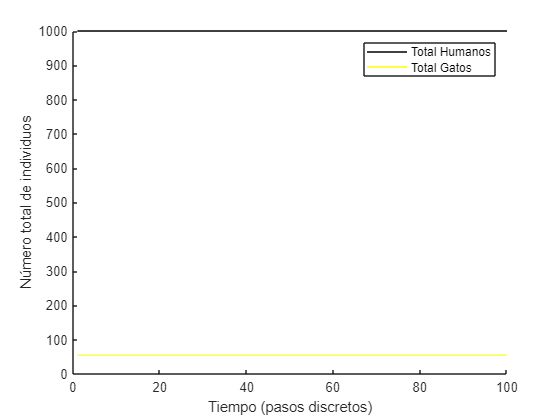


figure;
hold on;
plot(1:num_steps, Total_H_results, 'k', 'DisplayName', 'Total Humanos');
plot(1:num_steps, Total_G_results, 'y', 'DisplayName', 'Total Gatos');
xlabel('Tiempo (pasos discretos)');
ylabel('Número total de individuos');
legend;
hold off;